## Instructions

- Run each cell in order

- Modify the lines that have **green comments**

- This notebook by default assumes that: time/samples are rows and channels are columns

- Feel free to try more involved preprocessing steps, but make sure to assign your results back to the appropriate variables

## Preprocessing

### Step 1: Load the dataset

clearvars
load("datasets\training_dataset.mat")

### Step 2: Visualize the raw data

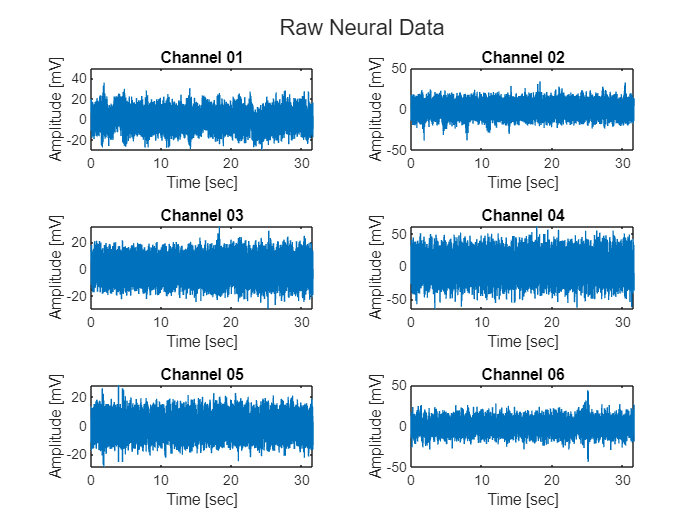

fig = plot_raw_data(experiment_data);

### Step 3: Filter the data

#### A. Provide information for designing the fiter

Assuming you want to use a high-pass filter to denoise the neural signals, answer the following questions:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% What is the sampling frequency of your signals in units of Hz?
sample_rate = 7; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 1; % Change this random value
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### B. Design the filter and apply it to the signal

The function `butter` designs a filter using three arguments: filter order, normalized cut off frequency, and filter type.

It returns the transfer function coefficients that match the provided specifications:


$$H(z) = \frac{B(z)}{A(z)} = \frac{b(1) + b(2)\,z^{-1} + b(n+1)\,z^{-n}}{a(1) + a(2)\,z^{-1} + a(n+1)\,z^{-n}}$$


filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter 

To apply the filter, we pass the transfer function to a precompiled method (`FilterX`) that has been optimized for speed

ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = FilterX(b, a, experiment_data.raw_neural_data, ch_init_conds);

#### Step 4: Visualize the Filtered Data

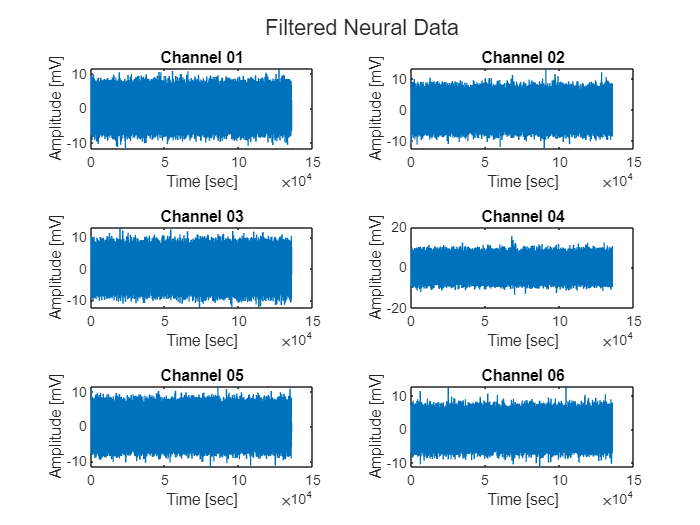

fig = plot_filt_data(filt_neural_data, sample_rate);

tic
passband = [20 30]; % passband frequency of filter in Hz (CHANGE THESE VALUES)
filtered_data = bandpass( double(experiment_data.raw_neural_data), ...
    passband, ...
    experiment_data.sample_rate);
toc

Elapsed time is 43.787954 seconds.


### Step 3. Visualize the filtered data

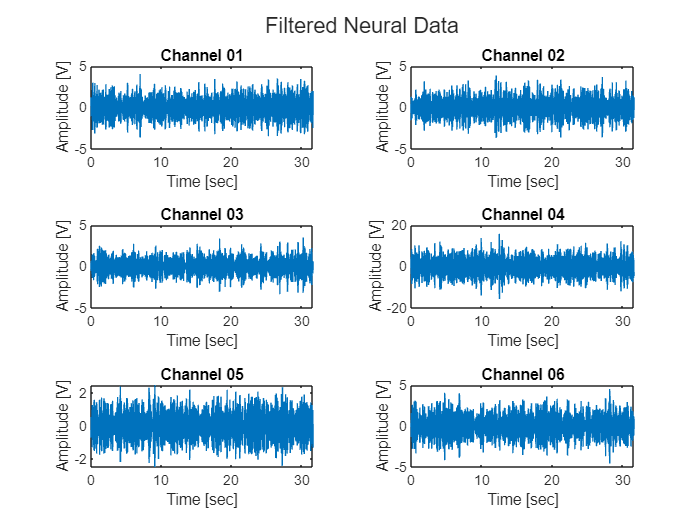

figure
fig_filt = tiledlayout("flow");
for i=1:num_chans
    nexttile
    plot(timestamps, filtered_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [V]')
end
title(fig_filt, 'Filtered Neural Data')

## Feature Extraction: Spike Trains

### Step 1. Use thresholding to detect spikes

Do literature review to find suitable formulas for the threshold you'll use for spike detection. You will need to specify on threshold for each channel

spike_threshold = 3.5*std(filtered_data) % thresholding formula (CHANGE THIS FORMULA)

spike_threshold =     3.6544    3.5945    2.9229   13.0682    2.4818    4.0499


### Step 2. Generate spike trains

Use your threshold to detect spikes. In this case the default code uses negative thresholding to detect spikes.

The result of your detection formula shoud be a `6xN` matrix. 

Each column of the `spike_train` matrix is a logical array with a value of `1` where a spike is detected, and `0` everywhere else.

spike_trains = diff(filtered_data < -1*spike_threshold) == 1; % spike detection formula (CHANGE THIS FORMULA)

### Step 3. Visualize the Spike Trains in a Raster Plot

The raster plot below shows the spikes detected in each channel contrasted with the kinematics.

Ideally, you'd want to see a concentration of spikes near the peaks of the kinematics, and no spikes during the resting periods.

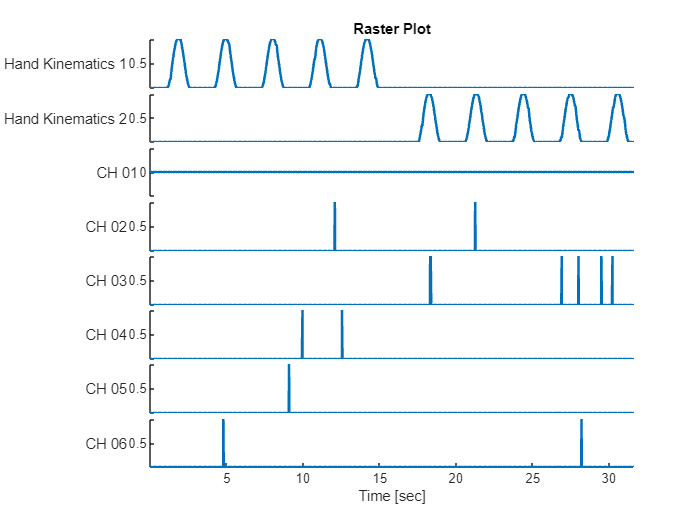

figure
fig_raster = stackedplot(timestamps(1:length(spike_trains)),[experiment_data.hand_kinematics(1:length(spike_trains),:), spike_trains], LineWidth=1.5);
fig_raster.DisplayLabels = ["Hand Kinematics 1", "Hand Kinematics 2", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
fig_raster.XLabel = "Time [sec]";
fig_raster.Title = "Raster Plot";

### Step 3. Plot the Action Potentials from the Spike Trains

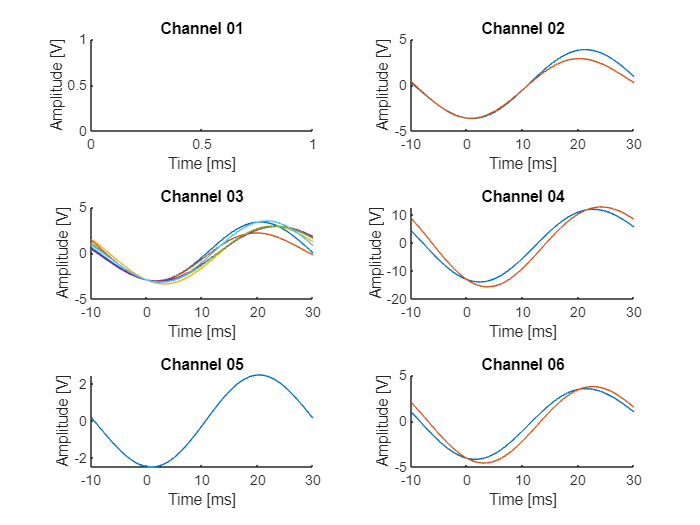

figure
fig_spike_train = tiledlayout('flow');
spike_before = 10e-3 * experiment_data.sample_rate; % Time [s] before the action potential crosses the threshold (CHANNGE THIS VALUE)
spike_after = 30e-3 * experiment_data.sample_rate;  % Time [s] after the action potential crosses the threshold (CHANGE THIS VALUE)
spike_duration = (-spike_before:spike_after)/experiment_data.sample_rate * 1e3;
for chan=1:num_chans
    nexttile
    spike_idxs = find(spike_trains(:, chan))';
    hold on
    for i = spike_idxs
        if i-spike_before < 1; continue; end
        if i+spike_after > num_samples; continue; end
        plot(spike_duration,filtered_data(i-spike_before:i+spike_after, chan))
    end
    hold off
    xlabel("Time [ms]")
    ylabel("Amplitude [V]")
    title(sprintf("Channel %02d", chan))
end

### Step N. Find the spike rate of each channel

## Helper Functions

function fig_handle = plot_raw_data(experiment_data)

[num_samples, num_chans] = size(experiment_data.raw_neural_data);
timestamps = (1:num_samples)/experiment_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    nexttile
    plot(timestamps, experiment_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [mV]')
end
title(fig_raw, 'Raw Neural Data')
end

function fig_handle = plot_filt_data(neural_data, sample_rate)

[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    nexttile
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [mV]')
end
title(fig_raw, 'Filtered Neural Data')
end